# Apuntes de clase - Probabilidades condicionales y variables aleatorias

Herramientas Matemáticas para el manejo de la información

Sesión 4 - 26 de febrero de 2026

# Para recordar...

Para la generación de variables aleatorias discretas, se puede utilizar una versión simplificada del método de la transformación inversa (que se estudiará posteriormente en el curso). Los pasos sugeridos son:

- Almacenar los $n$ resultados en un vector: $x = \{x_1,x_2,x_3,\dots,x_n\}$. 

- Realizar la partición del intervalo real $[0,1]$ en intervalos consecutivos, de manera tal que el tamaño del i-ésimo intervalo sea igual a la probabilidad del i-ésimo resultado, con $i=\{1,2,3,\dots,n\}$.

- Generar un número aleatorio uniformemente distribuído, con parámetros $0$ y $1$.

- Identificar a cuál de los $n$ intervalos pertenece el número aleatorio y almacenar el número del intervalo en $m$.

- Retornar el resultado $x_m$.

## Ejemplo

A continuación se encuentra la codificación de una función llamada `partido`, que retorna un número real de acuerdo a la siguiente tabla de probabilidades:


$$\begin{array}{cc}x & P[X=x] \\ 0 & 0.7 \\ 1 & 0.2 \\ 3 & 0.1
\end{array}$$


type partido.m

## Primer ejercicio

Codifique una función llamada nota que entregue la nota definitiva de un estudiante del curso.

## Estudiantes que resolvieron correctamente el ejercicio

## Segundo ejercicio

Codifique una función llamada `pruebapartido(repeticiones)` que realice una gráfica de barras con las frecuencias relativas resultantes de ejecutar la función `partido`, tantas veces como indique la variable `repeticiones`

## Estudiantes que resolvieron correctamente el ejercicio

## Prueba de la función `partido()`

partido()
pruebapartido(10000)

## Tercer ejercicio

Codifique una función llamada `dado()` que genere un número entero aleatorio distribuido uniformemente entre 1 y 6, inclusive.


$$\begin{array}{cc}
X & P[X=x] \\
1 & \frac{1}{6} \\
2 & \frac{1}{6} \\
3 & \frac{1}{6} \\
4 & \frac{1}{6} \\
5 & \frac{1}{6} \\
6 & \frac{1}{6}
\end{array}$$


## Estudiantes que resolvieron correctamente el ejercicio

dado()
pruebadado(1000000)

# Tarea 5

Codifique una función llamada `va(x,p)`, que retorne uno de los elementos del vector `x`, de acuerdo a las probabilidades dadas en el vector `p`. Tenga en cuenta que la función debe identificar, internamente, la cantidad de elementos que tiene el vector `x`. Por ejemplo, para ejecutar resultados equivalentes a los vistos en las últimas sesiones, se debe de escribir en la ventana de comandos:

Moneda:

va([0,1],[0.5,0.5])

Partido:

va([0,1,3],[0.7,0.2,0.1])

Dado:

va([1,2,3,4,5,6],[1/6,1/6,1/6,1/6,1/6,1/6]);

# Probabilidades Condicionales

Sean $A, B \subseteq \Omega$. Si $A \neq\{\}, B\neq\{\}$, entonces:


$$P[A \vert B] := \frac{P[A \cap B]}{P[B]}$$


 
$$P[B \vert A] := \frac{P[A \cap B]}{P[A]}$$


## Eventos Independientes

Sean $A, B \subseteq \Omega$. Con $A \neq\{\}, B\neq\{\}$. Los eventos A y B son independientes si y solo si:


$$P[A \vert B] = P[A]$$



$$P[B \vert A] = P[B]$$



$$P[A \cap B] =P[A]P[B]$$


## Ejercicio

¿Escogen los aspirantes de la maestría el énfasis de estudio, según su profesión?


$$\begin{array}{cccc}
 & \text{Inteligencia}&\text{Software}&\text{Geomática}&\text{Telemática}&\textbf{Total}\\
\text{Industrial} &2 & 0 & 0 & 0 & 2\\
\text{Sistemas} &3 & 0 & 0 & 0 & 3\\
\text{Electrónico} &1 & 0 & 0 & 0 & 1\\
\text{Producción} &0 & 1 & 0 & 0 & 1\\
\text{Catastral} &0 & 0 & 5 & 0 & 5\\
\text{Topográfica} &0 & 0 & 1 & 0 & 1\\
\textbf{Total} &6 & 1 & 6 & 0 & 13
\end{array}$$


# Variables Aleatorias

"No es variable, ni es aleatoria". Es una función que mapea (de manera determinista) los elementos de $\Omega$ en el conjunto de los números reales.


$$X:\Omega \to \mathbb{R}$$


Se llama variable porque es la variable independiente de otras funciones que dan información de la probabilidad, como lo son: la función de densidad de probabilidad o la esperanza matemática. Se llama aleatoria porque cada número real asignado proviene de un resultado del experimento aleatorio.

# Funciones

function fr = pruebapartido(repeticiones)
    resultados = zeros(1,repeticiones);
    for n = 1:repeticiones
        resultados(n) = partido();
    end


function resultado = partido()
    p = rand;
    if p < 0.7
        resultado = 0;
    elseif p < 0.9
        resultado = 1;
    else
        resultado = 3;
    end
end


    
    fr = zeros(1,3);
    
    fr(1)= sum(resultados == 0)/repeticiones;
    fr(2)= sum(resultados == 1)/repeticiones;
    fr(3)= sum(resultados == 3)/repeticiones;
    
    x = [0,1,3];
    bar(x,fr)
    colormap(summer)
    set(gca,'Fontsize',14);
    xlabel('Puntos Ganados');
    ylabel('Frecuencia Relativa');
    title(['Prueba de la función tras ',...
        num2str(repeticiones),' partidos']);

ans = 1

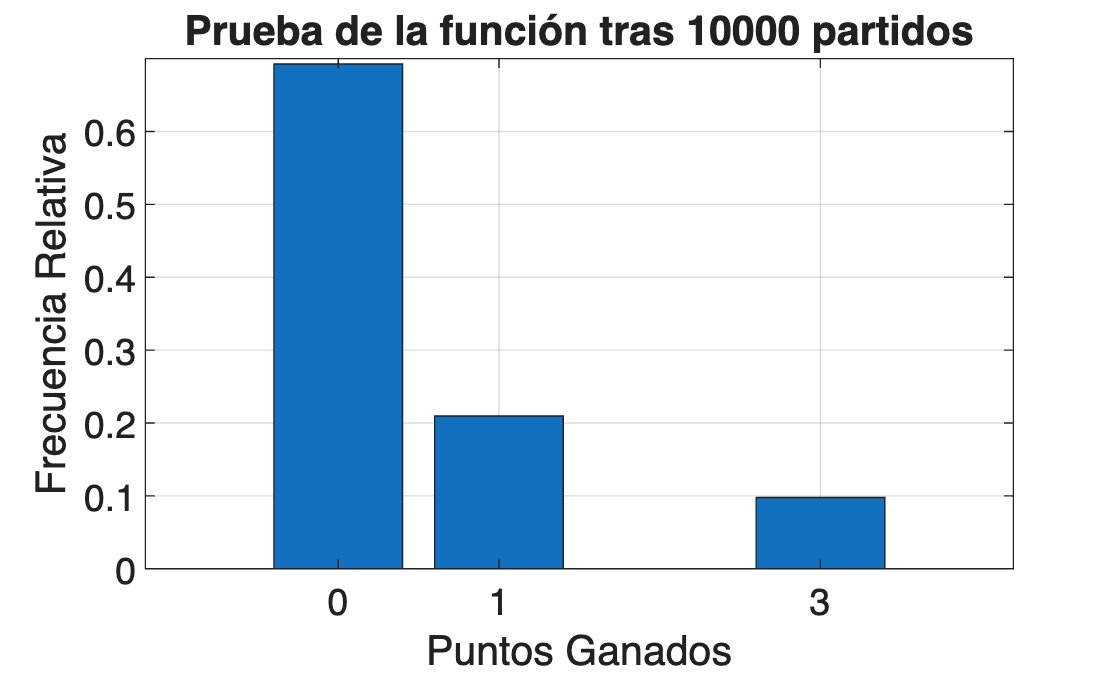

ans =     0.6926    0.2096    0.0978


    grid on;

    set(gcf,'Color','White');
    %print('/users/Hans/Desktop/partido','-dpng');
    %print('/users/Hans/Desktop/partido','-depsc');    
end

function y = dado()
    x = 1:6;
    pdf = (1/6)*ones(1,6);
    cdf = cumsum(pdf);

ans = 2

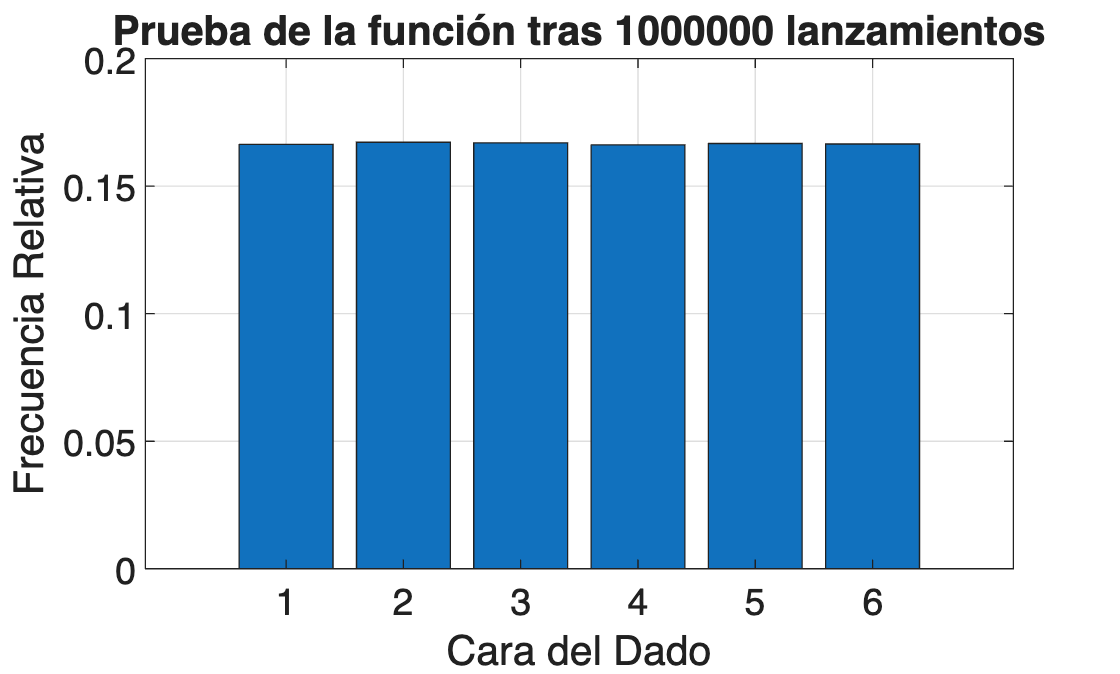

ans =     0.1664    0.1672    0.1670    0.1662    0.1667    0.1665


    p = rand;

    for n = 1:numel(cdf)
        if p<cdf(n)
            y = x(n);
            return;
        end

Como aún no he hecho la tarea, solo obtengo
este mensaje.


    end    
end

Como aún no he hecho la tarea, solo obtengo
este mensaje.



function fr = pruebadado(repeticiones)

Como aún no he hecho la tarea, solo obtengo
este mensaje.


    resultados = zeros(1,repeticiones);
    for n = 1:repeticiones
        resultados(n) = dado();
    end
    
    fr = zeros(1,6);
    
    for n = 1:6
        fr(n)= sum(resultados == n)/repeticiones;
    end
    
    x = 1:6;
    bar(x,fr)
    colormap(summer)
    set(gca,'Fontsize',14);
    xlabel('Cara del Dado');
    ylabel('Frecuencia Relativa');
    title(['Prueba de la función tras ',...
        num2str(repeticiones),' lanzamientos']);
    grid on;
    set(gcf,'Color','White');
    %print('/users/Hans/Desktop/partido','-dpng');
    %print('/users/Hans/Desktop/partido','-depsc');
end

function y = va(x,pdf)
    % codifique en este espacio la solución a su tarea
    disp('Como aún no he hecho la tarea, solo obtengo');
    disp('este mensaje.'); 
end